clear 
clc

load ifk.mat

[m,n] = size(d);
a = 0; b = 1;

n = m;

sig  = 5e-5;

dx = (b-a)/m;
g = @(x,y) x*exp(-x*y);

x = [];
for j = 1:n
    x = [x  a + (dx/2) + (j-1)*dx]; %form x
end
y = x;

G = zeros(m,n);

for i = 1:m
    for j = 1:n
        G(i,j) = g(x(j),y(i)).*dx; %form G
    end
end


%form L1 and L2 matrices
L1 = zeros(n-2,n-1);
for i=2:n-1
    for j=1:n
        L1(1,1) = -1;
        L1(1,2) = 1;
        if (i==j)
            L1(i,j) = -1;
        elseif (j==i+1) 
            L1(i,j) =1;
        end
    end
end
L1 

L1 =     -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0    -1     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0   

L2 = zeros(n-3,n-1);
for i=2:n-2
    for j=1:n
        L2(1,1) = 1;
        L2(1,2) = -2;
        L2(1,3) = 1;
        if (i==j)
            L2(i,j) = 1;
        elseif (j==i+1) 
            L2(i,j) = -2;
        elseif (j==i+2) 
            L2(i,j) = 1;
        end
    end
end
L2

L2 =      1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     1    -2     1     0     0     0     0     0     0     0     0     0     0
     0     0     0     0   

### No.2 Plot the predictive errors.

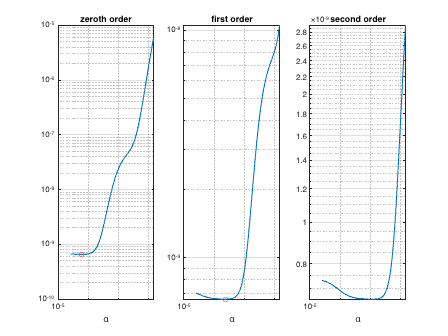

alpha_max = 0.0148; 
alpha_min = 2.5058e-5;

nbar = 100;
alp_i = [];
g0 = []; g1 =[]; g2 = [];
for i = 1:nbar
    apha = alpha_min*(alpha_max/alpha_min)^((nbar-i)/(nbar-1));
    alp_i = [alp_i apha];
    g0 = [g0 galpha(m,G,eye(m),d,apha)];
    g1 = [g1 galpha(m,G,L1,d,apha)];
    g2 = [g2 galpha(m,G,L2,d,apha)];
end

[op0 i0] = min(g0);
[op1 i1] = min(g1);
[op2 i2] = min(g2);

figure(1)
subplot(1,3,1)
loglog(alp_i,g0); hold on
loglog(alp_i(i0),op0,'or'); grid on
title('zeroth order');
xlabel('\alpha'); %ylabel('g(\alpha)')

subplot(1,3,2)
loglog(alp_i,g1); hold on
loglog(alp_i(i1),op1,'or'); grid on
title('first order');
xlabel('\alpha'); %ylabel('g(\alpha)')

subplot(1,3,3)
loglog(alp_i,g2); hold on
loglog(alp_i(i2),op2,'or'); grid on

title('second order');
xlabel('\alpha'); %ylabel('g(\alpha)')

### Discuss how you chose αmin and αmax and how you would chose an optimal value for α by looking at the graphs.

I used the minmum and maximum values of the alpha obtained from zeroth, first, and second order Tikhonov regularization of both the regularized and the non regularized discrepancy principles to yeild $\alpha_{min}$ and $\alpha_{max}$ respectively. The optimal value of $\alpha$ will be the value of $\alpha$ at which $g(\alpha)$ is minimum, and those are the red small circles in every plot.

function g = galpha(m,G,L,d,alpha)
    Gpound = (G'*G + (alpha^2).*L'*L)\G';
    m_alpha = Gpound*d;
    g = m*(norm(G*m_alpha - d)^2)/trace(eye(m) - G*Gpound)^2;

end
